oldparam = sympref('HeavisideAtOrigin',1);

# Laplace Transform

part one

syms t
f1 = t*heaviside(t-1);
f2 = sin(t)*exp(-4*t) * heaviside(t);
f3 = 2*t*cos (3*t)*heaviside(t);
laplace(f1)

$$ans = \frac{{\mathrm{e}}^{-s}}{s}+\frac{{\mathrm{e}}^{-s}}{s^{2}}$$

laplace(f2)

$$ans = \frac{1}{{\left(s+4\right)}^{2}+1}$$

laplace(f3)

$$ans = \frac{4\,s^{2}}{{\left(s^{2}+9\right)}^{2}}-\frac{2}{s^{2}+9}$$

part two

syms s
F1 = (1/(s*(s+1)))*exp(-3*s);
F2 = 4/(s*(s^2 +4));
F3 = 1/(s^2 + 3 * s + 1);
ilaplace(F1)

$$ans = -\mathrm{heaviside}\left(t-3\right)\,\left({\mathrm{e}}^{3-t}-1\right)$$

ilaplace(F2)

$$ans = 1-\cos\left(2\,t\right)$$

ilaplace(F3)

$$ans = \frac{2\,\sqrt{5}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sinh\left(\frac{\sqrt{5}\,t}{2}\right)}{5}$$

part three

G =(8)/(s^2 +s + 4)

$$G = \frac{8}{s^{2}+s+4}$$

delta_res = ilaplace(G)

$$delta\_res = \frac{16\,\sqrt{15}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)}{15}$$

step_res = ilaplace(G*(1/s))

$$step\_res = 2-2\,{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{15}\,t}{2}\right)+\frac{\sqrt{15}\,\sin\left(\frac{\sqrt{15}\,t}{2}\right)}{15}\right)$$

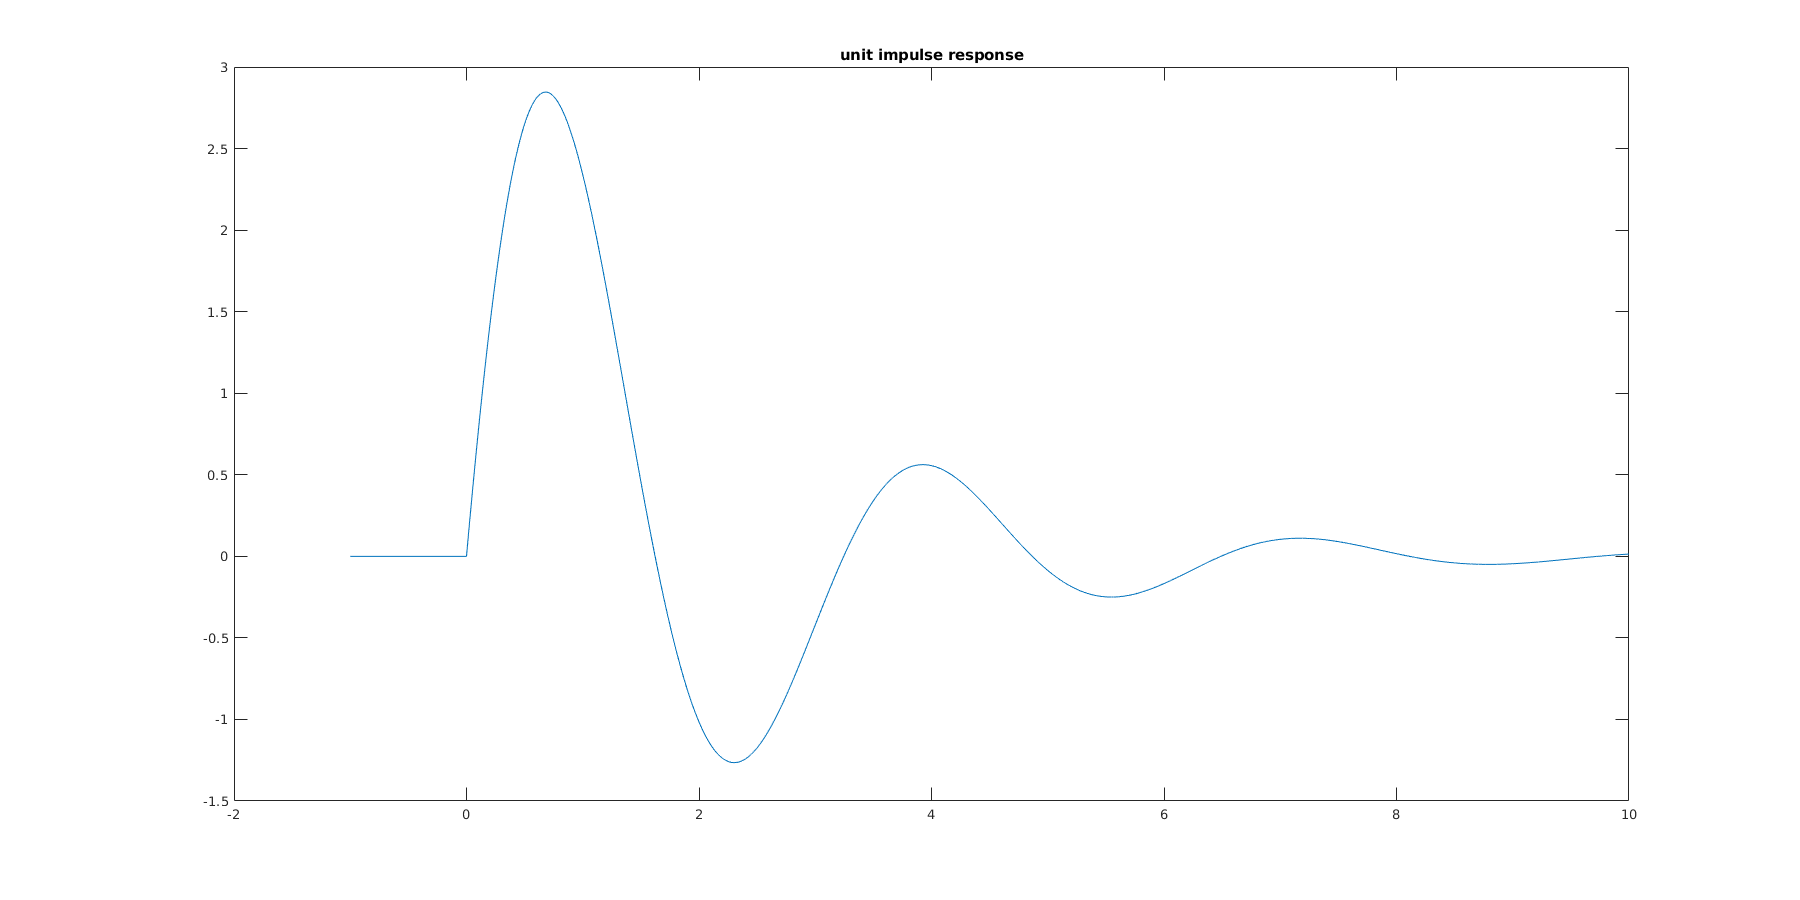

t = -1:0.001:10;
y2 = subs(delta_res,t) .* (t>=0);
plot_fig(t,y2,"unit impulse response")


t = -1:0.001:10;
y2 = subs(step_res,t) .* (t>=0);
plot_fig(t,y2,"step response")
H = tf([8],[1,1,4])

H =
 
       8
  -----------
  s^2 + s + 4
 
Continuous-time transfer function.



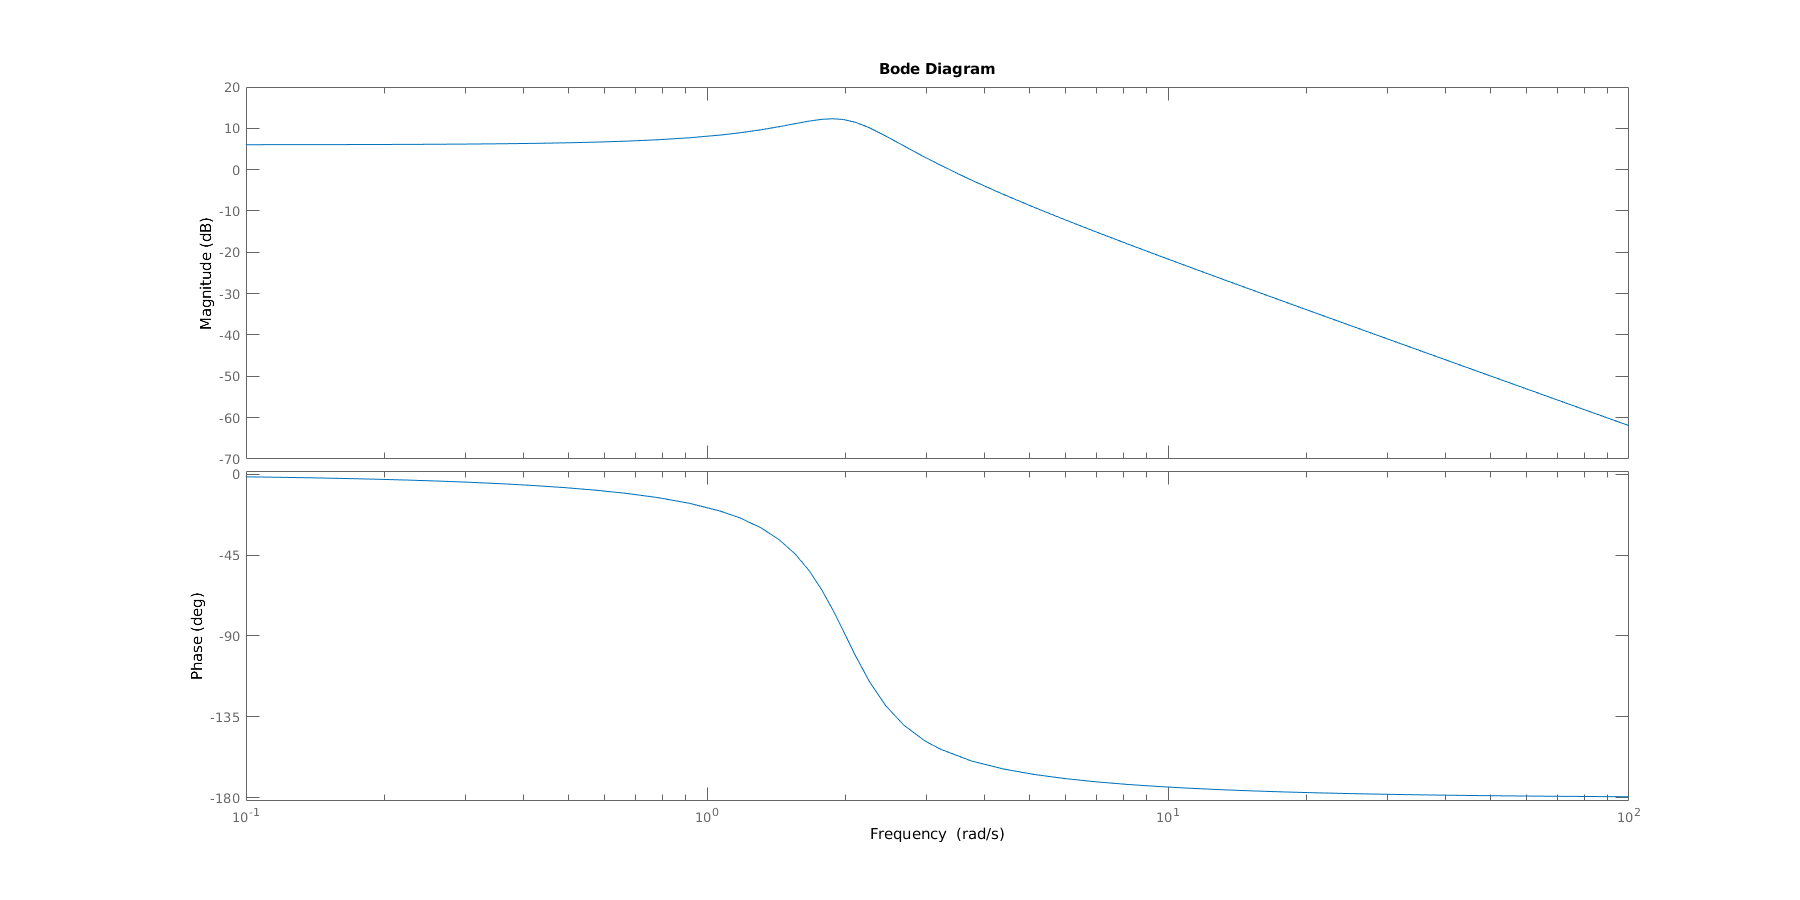

bode(H)

part four

a = 4

G =(2*s+1)/(s^2 + 4*s + 7)

$$G = \frac{2\,s+1}{s^{2}+4\,s+7}$$

step_res = ilaplace(G*(1/s))

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-2\,t}\,\left(\cos\left(\sqrt{3}\,t\right)-4\,\sqrt{3}\,\sin\left(\sqrt{3}\,t\right)\right)}{7}$$

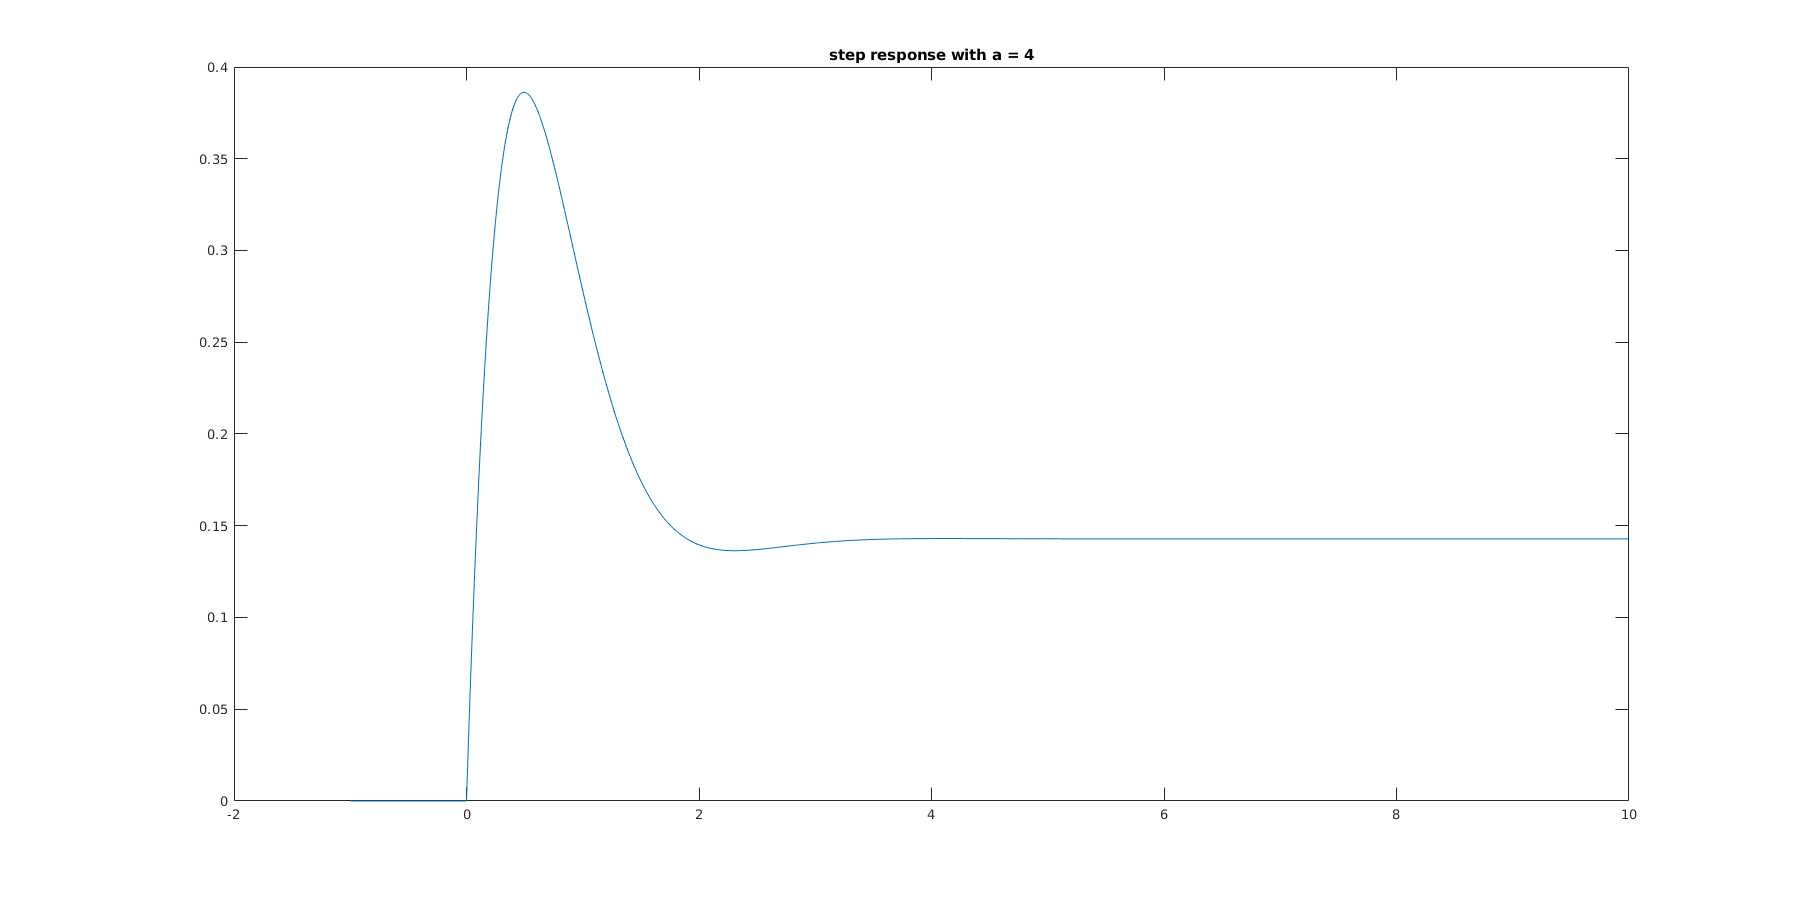

t = -1:0.001:10;
y2 = subs(step_res,t) .* (t>=0);
plot_fig(t,y2,"step response with a = 4")

clear t
syms t
step_res =  sym(1/7) - (exp((-2*t))*(cos(sqrt(sym(3))*t) - 4*sqrt(sym(3))*sin(sqrt(sym(3))*t)))/7

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-2\,t}\,\left(\cos\left(\sqrt{3}\,t\right)-4\,\sqrt{3}\,\sin\left(\sqrt{3}\,t\right)\right)}{7}$$

limit(step_res,t,Inf)

$$ans = \frac{1}{7}$$

t= 0:0.001:2;
y = subs(step_res,t) .* (t>=0);
[val,index] = max(y);
display("maximum at = ");

    "maximum at = "



display(t(index))

    0.4950



display("value of maximum is :")

    "value of maximum is :"



display(double(val))

    0.3862



a = 6

G =(2*s+1)/(s^2 + 6*s + 7)

$$G = \frac{2\,s+1}{s^{2}+6\,s+7}$$

step_res = ilaplace(G*(1/s))

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-3\,t}\,\left(\cosh\left(\sqrt{2}\,t\right)-\frac{11\,\sqrt{2}\,\sinh\left(\sqrt{2}\,t\right)}{2}\right)}{7}$$

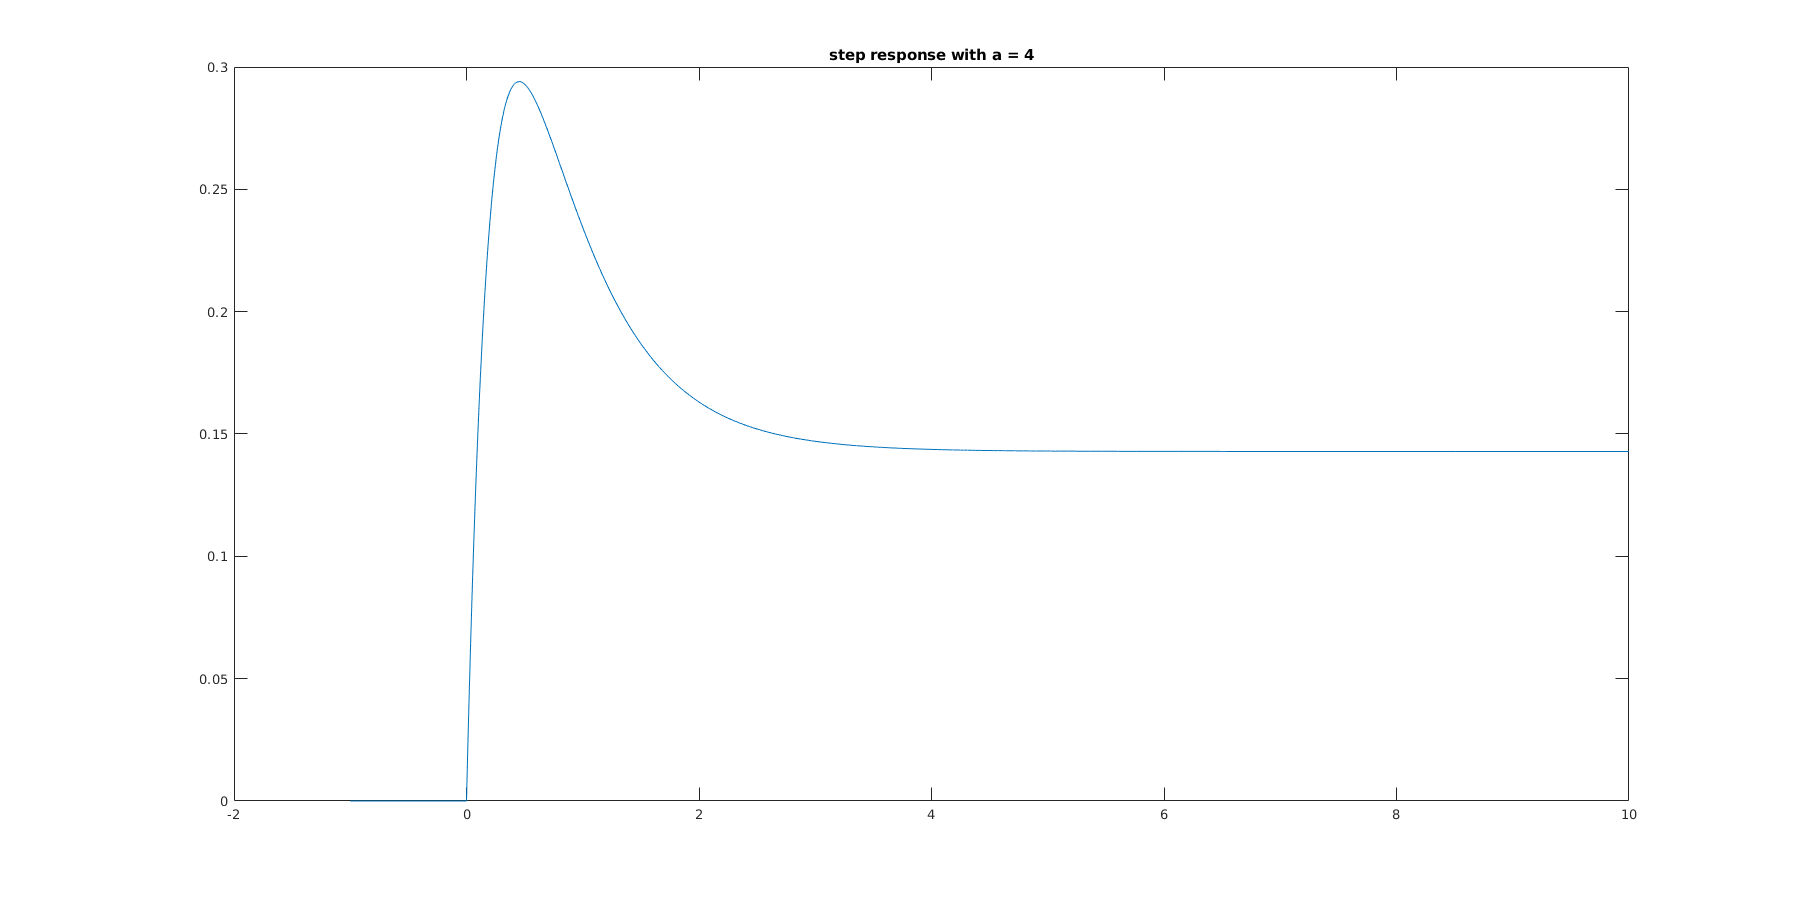

t = -1:0.001:10;
y2 = subs(step_res,t) .* (t>=0);
plot_fig(t,y2,"step response with a = 4")

clear t
syms t
step_res =  sym(step_res)

$$step\_res = \frac{1}{7}-\frac{{\mathrm{e}}^{-3\,t}\,\left(\cosh\left(\sqrt{2}\,t\right)-\frac{11\,\sqrt{2}\,\sinh\left(\sqrt{2}\,t\right)}{2}\right)}{7}$$

limit(step_res,t,Inf)

$$ans = \frac{1}{7}$$

t= 0:0.001:2;
y = subs(step_res,t) .* (t>=0);
[val,index] = max(y);
display("maximum at = ");

    "maximum at = "



display(t(index))

    0.4530



display("value of maximum is :")

    "value of maximum is :"



display(double(val))

    0.2940



# Z transform

part one